# **Implementation of Huffman Coding**

## **Huffman Coding:**

## Part 1)

            A) Designing a Huffman code for an English Language character set.   

            B) Calculating the code average length and compare it to the English Language Entropy.

            C) Encoding (Test1.txt) file using the constructed codebook.

## Part 2)

            A) Designing a Huffman code depending on the frequency in the text file.   

            B) Calculating the code average length and compare it to the Entropy of the Text file symbols.

            C) Encoding (Test1.txt) file using the constructed codebook.

## Part 3)

            A) Compare the total length of the encoded bits in both cases.  

## Comment on the results

### **Part 1)**

**A) Designing a Huffman code for an English Language character set.**

- **In order to design a Huffman code for an English Language character set, the probability of each character in the language is needed.**

- **Using the following table which contains English Letter Frequency based on a sample of 40,000 words.**

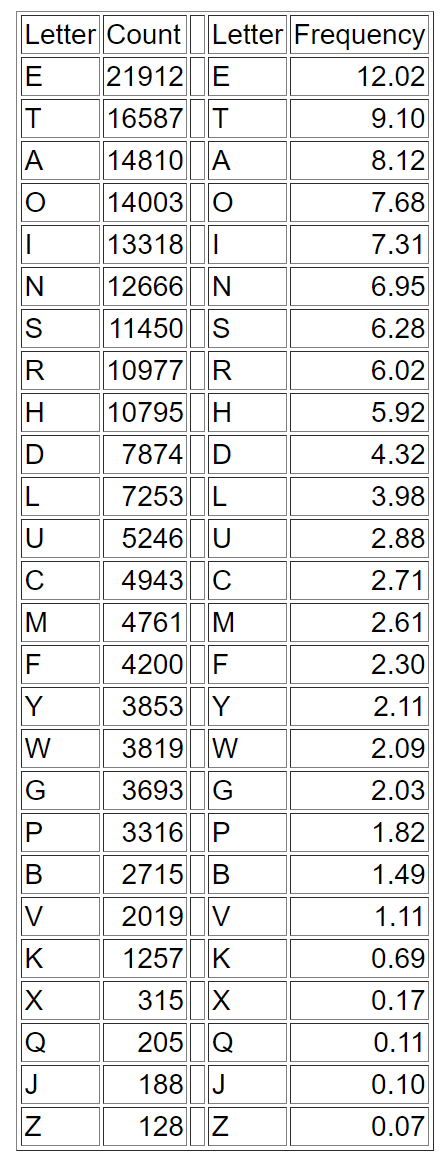

- **Functions used for this task are:**

- **GetHuffmanCodes: ***This function takes the charcters along with their probabilities and finds the Huffman Code for each Character.*

- **UpdateCodeWord: ***This function is a helper function to be used in ***GetHuffmanCodes ***in order to update the codes of the characters with the lowest probability in each iteration.*

clear;
close all;
clc;

chars_Arr = ['E', 'T', 'A', 'O', 'I', 'N', 'S', 'R', 'H', 'D', 'L', 'U', 'C', 'M', 'F', 'Y', 'W', 'G', 'P', 'B', 'V', 'K', 'X', 'Q', 'J', 'Z'];
freq_Arr = [12.02, 9.10, 8.12, 7.68, 7.31, 6.95, 6.28, 6.02, 5.92, 4.32, 3.98, 2.88, 2.71, 2.61, 2.30, 2.11, 2.09, 2.03, 1.82, 1.49, 1.11, 0.69, 0.17, 0.11, 0.10, 0.07];
probability_Arr = freq_Arr / sum(freq_Arr);
fprintf("The sum of probabilities is %f \n ",sum(probability_Arr) );

The sum of probabilities is 1.000000 
 


% Calculating the Entropy
entropy = 0;
for i = 1:length(probability_Arr)
    entropy = entropy - probability_Arr(i)*log2(probability_Arr(i));
end

% Getting the Huffman Codes for the Characters based on their probabilities
Huffman_codes_1 = GetHuffmanCodes(chars_Arr, probability_Arr);


% Printing the Code for each Character
fprintf("=======Codes for each Character=======")

=======Codes for each Character=======

for i = 1 : length(chars_Arr)
    fprintf("Character: %c , Code: %s \n", Huffman_codes_1.symbol(i), Huffman_codes_1.code{i} );

end

Character: E , Code: 100 
Character: T , Code: 111 
Character: A , Code: 0001 
Character: O , Code: 0010 
Character: I , Code: 0011 
Character: N , Code: 0101 
Character: S , Code: 0110 
Character: R , Code: 0111 
Character: H , Code: 1010 
Character: D , Code: 00000 
Character: L , Code: 01000 
Character: U , Code: 10110 
Character: C , Code: 10111 
Character: M , Code: 11000 
Character: F , Code: 11001 
Character: Y , Code: 11011 
Character: W , Code: 000010 
Character: G , Code: 000011 
Character: P , Code: 010010 
Character: B , Code: 010011 
Character: V , Code: 110101 
Character: K , Code: 1101000 
Character: X , Code: 110100100 
Character: Q , Code: 110100101 
Character: J , Code: 110100110 
Character: Z , Code: 110100111 


**B) Calculating the code average length and compare it to the English Language Entropy.**

- **In this part, the obtained codes from (A) are used to calculate the average length of codes.**

- **Additionally, the entopy is calculated using the provided probabilities.**


fprintf("\n======= B) Average Length and Entropy ======= \n")


======= B) Average Length and Entropy ======= 



% Calculating the Average Length
avg_len = 0;
for i = 1 : length(chars_Arr)
    avg_len = avg_len + length(Huffman_codes_1.code{i})* probability_Arr(i);
end
% Printing the entopy and Avg Length
fprintf("The entropy of the English Language is %f \n  ", entropy);

The entropy of the English Language is 4.181386 
  

fprintf("The Average Length of Huffman Codes is %f \n \n  ", avg_len);

The Average Length of Huffman Codes is 4.211921 
 
  

**C) Encoding (Test1.txt) file using the constructed codebook.**

- **In this part, the obtained codes are used to find the encoded sequence for the text file (Test1.txt)**

- **Functions used for this task are:**

- **HuffmanEncoder: ***This function takes the message to be encoded and the Huffman codes for each character in order to get the code sequence of the message.*

% Reading the text file
filetext = fileread('Test1.txt');

% Ecoding the message
encoded_message = HuffmanEncoder(filetext, Huffman_codes_1);



### **Part 2)**

**A) Designing a Huffman code depending on the frequency of occurrence of English letters in the text file given. **

- **In order to design a Huffman code for the frequency of each character in the text file is needed to be calculated.**

- **The obtained probabilities along with Characters will be passed to *****GetHuffmanCodes Function *****in order to find the codes of each symbol.**

- **Functions used for this task are:**

- **GetProbabilityAndEntropy: ***This function takes the content of the text file and extracts the unique characters in the file to calculate the frequency of each of them. Also, the entropy is calculated based on the obtained probability.*

- **GetHuffmanCodes: ***This function takes the charcters along with their probabilities and finds the Huffman Code for each Character.*

- **UpdateCodeWord: ***This function is a helper function to be used in ***GetHuffmanCodes ***in order to update the codes of the characters with the lowest probability in each iteration.*

file_name = "Test1.txt"; 
text = fileread(file_name);
fprintf("\n \n The Text file content is: \n%s \n \n",text );


 
 The Text file content is: 
THISISAPARAGRAPHTHATUSESEVERYSINGLELETTERINTHEALPHABETNOWTHATDOESNTMEANTHISCANBEAPARAGRAPHWITHNOSTORYBUTITDOESMEANTHATEVERYSINGLELETTERISUSEDYOUCANMAKEITASGENERICORFANCIFULASYOUDLIKEYOUCANTALKABOUTANYTHINGFROMQUILTSTOJETSTOXYLOPHONESOHYEAHANDYOUCANUSEWHATEVERLANGUAGEYOUWANTFROMAFRIKAANSTOZULUTHISISAPARAGRAPHTHATUSESEVERYSINGLELETTERINTHEALPHABETNOWTHATDOESNTMEANTHISCANBEAPARAGRAPHWITHNOSTORYBUTITDOESMEANTHATEVERYSINGLELETTERISUSEDYOUCANMAKEITASGENERICORFANCIFULASYOUD 
 



[probability_Arr2, entropy_2, chars_2] = GetProbabilityAndEntropy(text); 

for i = 1: length(probability_Arr2)
    fprintf("Character: %c, Probability = %f  \n", chars_2(i), probability_Arr2(i) );
end

Character: A, Probability = 0.118896  
Character: B, Probability = 0.014862  
Character: C, Probability = 0.021231  
Character: D, Probability = 0.019108  
Character: E, Probability = 0.110403  
Character: F, Probability = 0.014862  
Character: G, Probability = 0.027601  
Character: H, Probability = 0.053079  
Character: I, Probability = 0.059448  
Character: J, Probability = 0.002123  
Character: K, Probability = 0.010616  
Character: L, Probability = 0.038217  
Character: M, Probability = 0.016985  
Character: N, Probability = 0.070064  
Character: O, Probability = 0.059448  
Character: P, Probability = 0.023355  
Character: Q, Probability = 0.002123  
Character: R, Probability = 0.055202  
Character: S, Probability = 0.070064  
Character: T, Probability = 0.106157  
Character: U, Probability = 0.044586  
Character: V, Probability = 0.010616  
Character: W, Probability = 0.012739  
Character: X, Probability = 0.002123  
Character: Y, Probability = 0.033970  
Character: Z, Probability


% Printing the Entropy and sum of probability
fprintf("The sum of probabilities is %f \n ",sum(probability_Arr2) );

The sum of probabilities is 1.000000 
 


% Getting the Huffman Codes for the Characters based on their probabilities
Huffman_codes_2 = GetHuffmanCodes(chars_2, probability_Arr2);

% Printing the Code for each Character
fprintf("=======Codes for each Character=======")

=======Codes for each Character=======

for i = 1 : length(chars_2)
    fprintf("Character: %c , Code: %s \n", Huffman_codes_2.symbol(i), Huffman_codes_2.code{i} );

end

Character: A , Code: 011 
Character: B , Code: 100101 
Character: C , Code: 000100 
Character: D , Code: 001000 
Character: E , Code: 101 
Character: F , Code: 100100 
Character: G , Code: 10011 
Character: H , Code: 1101 
Character: I , Code: 1000 
Character: J , Code: 000101111 
Character: K , Code: 0001010 
Character: L , Code: 00011 
Character: M , Code: 001001 
Character: N , Code: 0100 
Character: O , Code: 0101 
Character: P , Code: 000001 
Character: Q , Code: 000101110 
Character: R , Code: 1100 
Character: S , Code: 0011 
Character: T , Code: 111 
Character: U , Code: 00001 
Character: V , Code: 0000001 
Character: W , Code: 0000000 
Character: X , Code: 000101101 
Character: Y , Code: 00101 
Character: Z , Code: 000101100 


**B) Calculating the code average length and compare it to the Entropy of the Text file symbols.**

- **In this part, the obtained codes from (A) are used to calculate the average length of codes.**

- **Additionally, the entopy is calculated using the calculated probabilities.**

% Calculating the Average Length
avg_len_2 = 0;
for i = 1 : length(chars_2)
    avg_len_2 = avg_len_2 + length(Huffman_codes_2.code{i})* probability_Arr2(i);
end

fprintf("\n ======= B) Average Length and Entropy ======= \n")


 ======= B) Average Length and Entropy ======= 


% Printing the entopy and Avg Length
fprintf("\n \nThe entropy of the Symbols in the Text File is %f \n  ", entropy_2);


 
The entropy of the Symbols in the Text File is 4.154499 
  

fprintf("The Average Length of Huffman Codes is %f \n \n  ", avg_len_2);

The Average Length of Huffman Codes is 4.174098 
 
  

**C) Encoding (Test1.txt) file using the constructed codebook.**

- **In this part, the obtained codes are used to find the encoded sequence for the text file (Test1.txt)**

- **Functions used for this task are:**

- **HuffmanEncoder: ***This function takes the message to be encoded and the Huffman codes for each character in order to get the code sequence of the message.*

% Ecoding the message
encoded_message_2 = HuffmanEncoder(text, Huffman_codes_2);


### **Part 3)**

**A) Comparing the total length of the encoded bits in both cases.**

fprintf("\n ======= 3) Comparing both Cases ======= \n")


 ======= 3) Comparing both Cases ======= 



% Length of the Encoded Sequence in part 1
fprintf("Total Length of bits in Case 1 is: %f \n  ", length(encoded_message));

Total Length of bits in Case 1 is: 1990.000000 
  

fprintf("Efficieny in Case 1 is: %f %% \n \n  ", 100*entropy/avg_len);

Efficieny in Case 1 is: 99.275021 % 
 
  


% Length of the Encoded Sequence in part 2
fprintf("Total Sequence bits in Case 2 is: %f \n ", length(encoded_message_2));

Total Sequence bits in Case 2 is: 1966.000000 
 

fprintf("Efficieny in Case 1 is: %f %% \n \n  ", 100*entropy_2/avg_len_2);

Efficieny in Case 1 is: 99.530469 % 
 
  

## **Comment on the obtained Efficiencies in both cases:**

***It is convienient that case 2 has more efficiency that case 1 since the obtained probabilities in case 2 are based on the frequency of characters in the given file, not in English Language in general. That is the reason behind having a slightly better efficieny in case 2 than in case 1.***